clc
close all

startIns = 1;
endIns = 50;

% rates = [0.2,0.4,0.6,0.8,1.0];
% effects = [0.2,0.4,0.6,0.8,1.0];

rates = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0];
effects = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9,1.0];

u = '_2.0';

wid = 800;
len = 300;

systemNo = 500;
metric_makespan = 'makespan_';
metric = 'makespan_abs_';

legend_labels= ["AJLR","CARVB"];
legend_position1= 'northwest';
legend_position2= 'vertical';

traditional_xticklables = ["10%","20%","30%","40%","50%" ,"60%","70%","80%","90%","100%"];
xticklables1 = ["r = 10%","r = 20%","r = 30%","r = 40%","r = 50%" ,"r = 60%","r = 70%","r = 80%","r = 90%","r = 100%"];
% xticklables1 = ["","","","","" ];
xticklables2 = ["e = ±10%","e = ±20%","e = ±30%","e = ±40%","e = ±50%" ,"e = ±60%","e = ±70%","e = ±80%","e = ±90%","e = ±100%" ];
% xticklables2 = ["","","","","" ];
xticklables = [xticklables1;xticklables2];
tickLabels = strtrim(sprintf('%s\\newline%s\n', xticklables{:}));

start_method = 2;

p1_ary = [0 1 5 ];
p2_ary = [100 99 95 ];

colors=[[0 0.4470 0.7410]; [0.8500 0.3250 0.0980];  [0.9290 0.6940 0.1250]; [0.4940 0.1840 0.5560];[0.4660 0.6740 0.1880]; [0.3010 0.7450 0.9330];[0.6350 0.0780 0.1840]];

methodToDisplay = 1;


## boxplot_makespan_medain

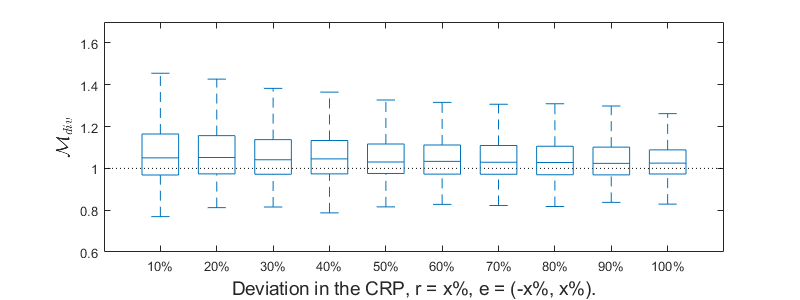

alldata_median = [];

f=figure('Position', [100, 100, wid, len]);
set(f,'defaultAxesColorOrder',[[0,60/255,255/255];[1,51/255,51/255]]);


line([0 length(effects)*methodToDisplay+1],[1.0 1.0],'Color','k','LineStyle',':','LineWidth',0.3);
hold on;

for indexK = 1:length(effects)
    rate = rates(indexK);
    if(rate == 1.0)
        rate = 1;
    end
    effect = effects(indexK);
    
    file_name = strcat('../error_crp_',num2str(rate),'_',num2str(effect),'/');
    data = readmatrix(strcat(file_name,metric ,'1', u, '.txt'));
    
    rowsNum = size(data,1);
    
    methodNum = rowsNum/systemNo;
    
    dataByMethod = cell(1,methodNum);
    
    % get data by each method
    for m = 1: methodNum
        startIndex = 1 + (m-1) * systemNo;
        endIndex = m * systemNo;
        dataByMethod{m} = data(startIndex :endIndex,startIns:endIns);
    end
    
    data_per_util = [];
    for m=start_method:methodNum
        datam = dataByMethod{m};
        d = reshape(median(datam'),[],1);
        data_per_util =[data_per_util d];
    end
    
    
    methodToDisplay = 1;
    pos = zeros(1);
    for col = 1:methodToDisplay
        pos(col) = (indexK - 1) * methodToDisplay + col;
    end
    
    alldata_median = [alldata_median data_per_util(:,2)./data_per_util(:,1)];
    
    for c = 1:methodToDisplay
        boxplot(data_per_util(:,2)./data_per_util(:,1), 'position',pos(c), 'widths', 0.65, 'symbol','', 'color', colors(c,:));
        hold on
    end
    
    
end

xlim([0 length(effects)+1]);
ylim([0.6 1.7]);
% ylim([13000 17000]);
xticks = sum(1:methodToDisplay)/methodToDisplay : methodToDisplay : length(effects)*methodToDisplay;


set(gca,'xtick',xticks );
set(gca,'xticklabel',traditional_xticklables);

% ax = gca();
% ax.TickLabelInterpreter = 'tex';
% ax.XTickLabel = '';
% 
% for i = 1:length(effects)
%     text(i, ax.YLim(1), sprintf('%s\n%s', xticklables{:,i}), ...
%         'horizontalalignment', 'center', 'verticalalignment', 'top');
% end
% ax.FontSize = 12;
% ax.XLabel.String = sprintf('\n\n%s', 'Deviation in the CRP');

xlabel('Deviation in the CRP, r = x%, e = (-x%, x%).','FontSize', 14)
ylabel('$\mathcal{M}_{div}$','Interpreter','latex','FontSize', 14)

set(gcf, 'PaperSize', [25 25])
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_medain_divide.png'));
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_medain_divide.eps'), 'epsc');


median_mean = 1 - mean(mean(alldata_median))

median_mean = -0.0534

median_max = 1 - max(max(alldata_median))

median_max = -0.9108

## boxplot_makespan_upper

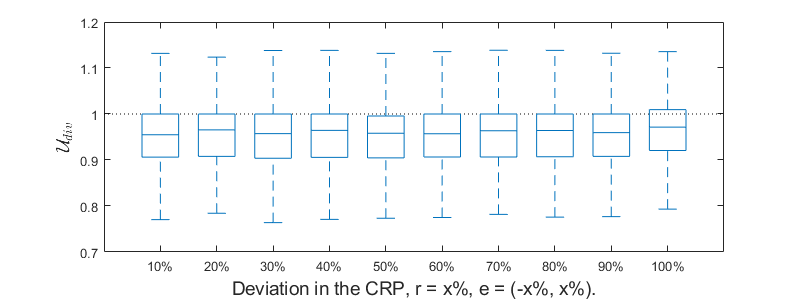

alldata = [];

p = 2;
p2 = p2_ary(p);


f=figure('Position', [100, 100, wid, len]);
set(f,'defaultAxesColorOrder',[[0,60/255,255/255];[1,51/255,51/255]]);

line([0 length(effects)*methodToDisplay+1],[1.0 1.0],'Color','k','LineStyle',':','LineWidth',0.3);
hold on;

for indexK = 1:length(effects)
    rate = rates(indexK);
    if(rate == 1.0)
        rate = 1;
    end
    effect = effects(indexK);
    
    file_name = strcat('../error_crp_',num2str(rate),'_',num2str(effect),'/');
    data = readmatrix(strcat(file_name,metric ,'1', u, '.txt'));
    
    rowsNum = size(data,1);
    
    methodNum = rowsNum/systemNo;
    dataByMethod = cell(1,methodNum);
    
    % get data by each method
    for m = 1: methodNum
        startIndex = 1 + (m-1) * systemNo;
        endIndex = m * systemNo;
        dataByMethod{m} = data(startIndex :endIndex,:);
    end
    
    data_per_util = [];
    for m=start_method:methodNum
        datam = dataByMethod{m};
        d = reshape(prctile(datam', p2,1),[],1);
        data_per_util =[data_per_util d];
    end
    
    methodToDisplay = 1;
    
    pos = zeros(1);
    for col = 1:methodToDisplay
        pos(col) = (indexK - 1) * methodToDisplay + col;
    end
    
    alldata = [alldata data_per_util(:,2)./data_per_util(:,1)];
    
    for c = 1:methodToDisplay
        boxplot(data_per_util(:,2)./data_per_util(:,1), 'position',pos(c), 'widths', 0.65, 'symbol','', 'color', colors(c,:));
        hold on
    end
end

xlim([0 length(effects)*methodToDisplay+1]);
% ylim([13000 17000]);
ylim([0.7 1.2]);
xticks = sum(1:methodToDisplay)/methodToDisplay : methodToDisplay : length(effects)*methodToDisplay;

set(gca,'xtick',xticks );
set(gca,'xticklabel',traditional_xticklables);

% ax = gca();
% ax.TickLabelInterpreter = 'tex';
% ax.XTickLabel = '';
% 
% for i = 1:length(effects)
%     text(i, ax.YLim(1), sprintf('%s\n%s', xticklables{:,i}), ...
%         'horizontalalignment', 'center', 'verticalalignment', 'top');
% end
% ax.FontSize = 12;
% ax.XLabel.String = sprintf('\n\n%s', 'Deviation in the CRP');

xlabel('Deviation in the CRP, r = x%, e = (-x%, x%).','FontSize', 14)
ylabel('$\mathcal{U}_{div}$','Interpreter','latex','FontSize', 14)


set(gcf, 'PaperSize', [25 25])
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_divide_',num2str(p2),'.png'));
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_divide_',num2str(p2),'.eps'), 'epsc');



upper_mean = 1- mean(mean(alldata))

upper_mean = 0.0448


upper_max = 1 -  min(min(alldata))

upper_max = 0.2885

## boxplot_variation

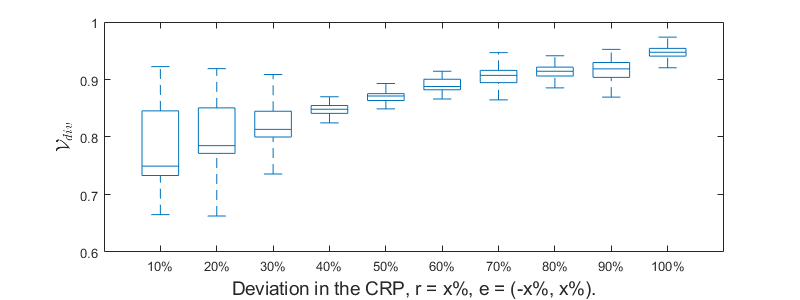

alldata = [];
p = 2;
p1 = p1_ary(p);
p2 = p2_ary(p);

f=figure('Position', [100, 100, wid, len]);
set(f,'defaultAxesColorOrder',[[0,60/255,255/255];[1,51/255,51/255]]);

for indexK = 1:length(effects)
    rate = rates(indexK);
    if(rate == 1.0)
        rate = 1;
    end
    effect = effects(indexK);
    
    file_name = strcat('../error_crp_',num2str(rate),'_',num2str(effect),'/');
    data = readmatrix(strcat(file_name,metric ,'1', u, '.txt'));
    
    rowsNum = size(data,1);
    
    methodNum = rowsNum/systemNo;
    dataByMethod = cell(1,methodNum);
    
    % get data by each method
    for m = 1: methodNum
        startIndex = 1 + (m-1) * systemNo;
        endIndex = m * systemNo;
        dataByMethod{m} = data(startIndex :endIndex,:);
    end
    
    data_per_util = [];
    for m=start_method:methodNum
        datam = dataByMethod{m};
        datam = datam(:,startIns:endIns);
        
        datam_std = std(datam');
        data_per_util =[data_per_util prctile(datam_std', p1:p2,'all')];
    end
    
    methodToDisplay = 1;
    
    pos = zeros(1);
    for col = 1:methodToDisplay
        pos(col) = (indexK - 1) * methodToDisplay + col;
    end
    
    alldata = [alldata data_per_util(:,2)./data_per_util(:,1)];
    
    for c = 1:methodToDisplay
        boxplot(data_per_util(:,2)./data_per_util(:,1), 'position',pos(c), 'widths', 0.65, 'symbol','', 'color', colors(c,:));
        hold on
    end
end

xlim([0 length(effects)*methodToDisplay+1]);
ylim([0.6 1]);
%     if(p==1)
%         ylim([0 3000]);
%     end

xticks = sum(1:methodToDisplay)/methodToDisplay : methodToDisplay : length(effects)*methodToDisplay;
set(gca,'xtick',xticks );
set(gca,'xticklabel',traditional_xticklables);


% ax = gca();
% ax.TickLabelInterpreter = 'tex';
% ax.XTickLabel = '';
% 
% for i = 1:length(effects)
%     text(i, ax.YLim(1), sprintf('%s\n%s', xticklables{:,i}), ...
%         'horizontalalignment', 'center', 'verticalalignment', 'top');
% end
% ax.FontSize = 12;
% ax.XLabel.String = sprintf('\n\n%s', 'Deviation in the CRP');

xlabel('Deviation in the CRP, r = x%, e = (-x%, x%).','FontSize', 14)
ylabel('$\mathcal{V}_{div}$','Interpreter','latex','FontSize', 14)


set(gcf, 'PaperSize', [25 25])
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_diff_divide_',num2str(p1),'_',num2str(p2),'.png'));
saveas(gcf,strcat('../CARVB_figs/ep_error_crp_compare_diff_divide_',num2str(p1),'_',num2str(p2),'.eps'), 'epsc');


vary_mean = 1- mean(mean(alldata))

vary_mean = 0.1279


vary_max = 1 - min(min(alldata))

vary_max = 0.3374